## **PROCESSING EMG DATA**

This script tries to analyze the data acquired by EMG electrodes placed on the vastus lateralis and biceps femoralis in order to obtain their RMS values in a 100-ms window for making comparisons between healthy patients and osteoporotic ones.

clear all
clc
close all

### Loading of EMG signals for vastus lateralis

vastus = csvread('EMG_vastus_lateralis_Zia_20_05_1_old.csv'); %vastus lateralis signal
biceps= csvread('EMG_biceps_femoris_Zia_20_05_1.csv'); %biceps femoralis signal

Signal parameters

fc=load('Sampling_frequency_vastus_Zia_20_05_1.txt'); %measured during data acquisition
fc_2=load('Sampling_frequency_biceps_Zia_20_05_1.txt'); %measured during data acquisition

fc=max(max(fc),max(fc_2)); 

f_low = 20; 
f_high = 450;

Calculation of acquisition time and time axes

min_sig=min(length(vastus),length(biceps));

vastus=vastus(1:min_sig);
biceps=biceps(1:min_sig);

T=size(vastus,1)/fc;
t=0:1/fc:(T-1/fc);

Take a look at the newly acquired signals

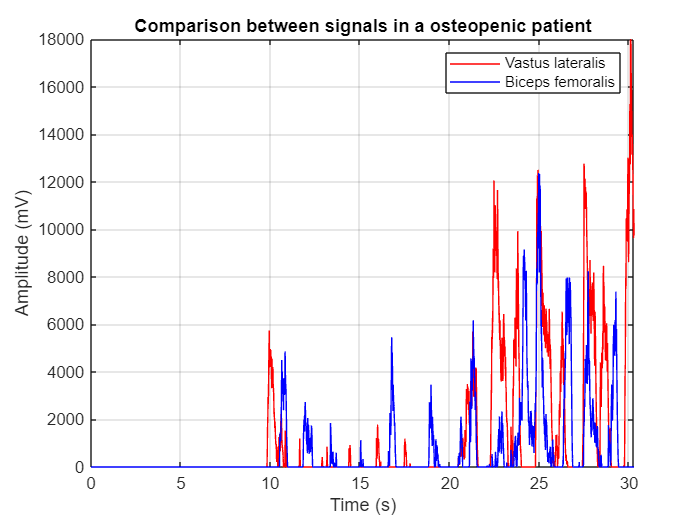

figure()
plot(t,vastus,'r',t,biceps,'b'), title('Comparison between signals in a osteopenic patient');
xlabel('Time (s)');
ylabel('Amplitude (mV)');
grid on;
legend('Vastus lateralis','Biceps femoralis'), axis tight;

### **Filtering the signal with a second-order Butterworth filter**

Signal has already been filtered between 20 and 450 Hz; there's no need to remove the mean value because it has already been eliminated.

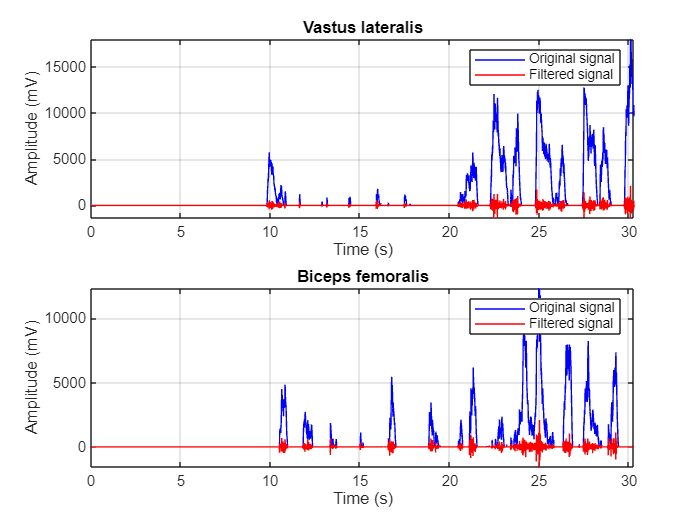

[b, a] = butter(2, [f_low, f_high] / (fc/2), 'bandpass');
vastus_filtered = filtfilt(b, a, vastus);
biceps_filtered = filtfilt(b, a, biceps);

figure
% Subplot 1: comparison between original healthy signal and filtered healthy signal
subplot(2,1,1);
plot(t, vastus, 'b', t, vastus_filtered, 'r');
xlabel('Time (s)');
ylabel('Amplitude (mV)');
grid on;
title('Vastus lateralis'),legend('Original signal', 'Filtered signal'),axis tight;

% Subplot 2: comparison between original osteoporotic signal and filtered osteoporotic signal
subplot(2,1,2);
plot(t, biceps, 'b', t, biceps_filtered, 'r');
xlabel('Time (s)');
ylabel('Amplitude (mV)');
grid on;
title('Biceps femoralis'),legend('Original signal', 'Filtered signal'),axis tight;

### **Normalization to MVIC (Maximum Voluntary Isometric Contraction)**

According to the protocol, an isolated acquisition is made in which the patient is asked to contract for a maximum of 5' with the leg in extension and take the average value from these acquisitions as the MVIC value. 

%max_sig=max(max(vastus_filtered),max(biceps_filtered));

vastus_max = csvread('EMG_vastus_lateralis_Zia_20_05_max_1.csv'); %vastus lateralis signal during MIVC
biceps_max = csvread('EMG_biceps_femoris_Zia_20_05_max_1.csv'); %biceps femoris signal during MIVC

mean_sig=mean(vastus_max);
vastus_normalized = vastus_filtered / mean_sig;

mean_sig=mean(biceps_max);
biceps_normalized = biceps_filtered / mean_sig;

Plot of the normalized signals

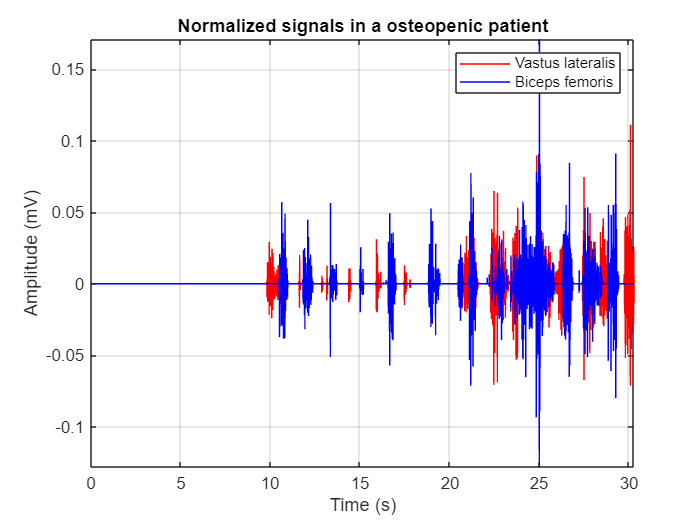

figure()
plot(t,vastus_normalized,'r',t,biceps_normalized,'b');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;
title('Normalized signals in a osteopenic patient'), legend('Vastus lateralis','Biceps femoris'),axis tight; 

Signal is too variable to have a single threshold, it is better to split it.

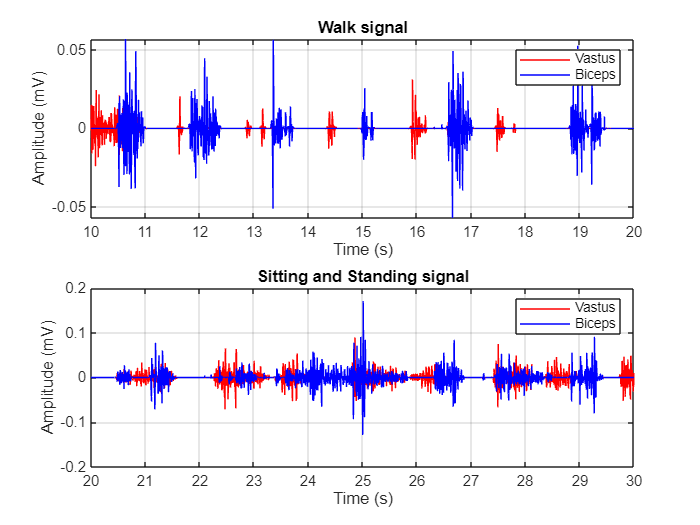

start_time_1 = 10; 
end_time_1 = 20;   
start_time_2 = 20; 
end_time_2 = 30;  

indices_1 = t >= start_time_1 & t < end_time_1;
indices_2 = t >= start_time_2 & t <= end_time_2;

walk_v = vastus_normalized(indices_1);
sit_stend_v = vastus_normalized(indices_2);
walk_b = biceps_normalized(indices_1);
sit_stend_b = biceps_normalized(indices_2);

t_walk_v = t(indices_1);
t_sit_stend_v = t(indices_2);

figure()
subplot(2,1,1);
plot(t_walk_v, walk_v,'r',t_walk_v, walk_b,'b');
title('Walk signal');
legend('Vastus', 'Biceps');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(2,1,2);
plot(t_sit_stend_v, sit_stend_v,'r',t_sit_stend_v, sit_stend_b,'b');
title('Sitting and Standing signal');
legend('Vastus', 'Biceps');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

By selecting a threshold based on the signals just observed, it is possible to find signal peaks.

Let's analyze the walking signal

[pks, locs] = findpeaks(walk_v, 'MinPeakHeight', 0.007); % Imposta la soglia corretta
[pks1, locs1] = findpeaks(walk_b, 'MinPeakHeight', 0.012); % Imposta la soglia corretta

figure()
plot(t_walk_v, walk_v, 'b', t_walk_v, walk_b, 'r');
title('Peaks in walk signal (osteopenic patient)');
axis tight;
grid on;

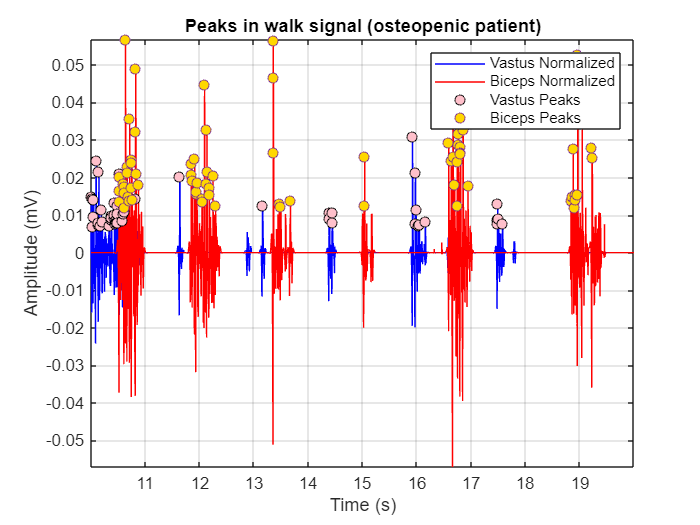

hold on;

plot(t_walk_v(locs), pks, 'ko', 'MarkerFaceColor', '#FFC0CB');
plot(t_walk_v(locs1), pks1, 'o', 'MarkerFaceColor', '#FFD700');
legend('Vastus Normalized', 'Biceps Normalized', 'Vastus Peaks', 'Biceps Peaks');
xlabel('Time (s)');
ylabel('Amplitude (mV)');
grid on;
hold off;

Let's analyze the signal acquired during the sitting/standing activities

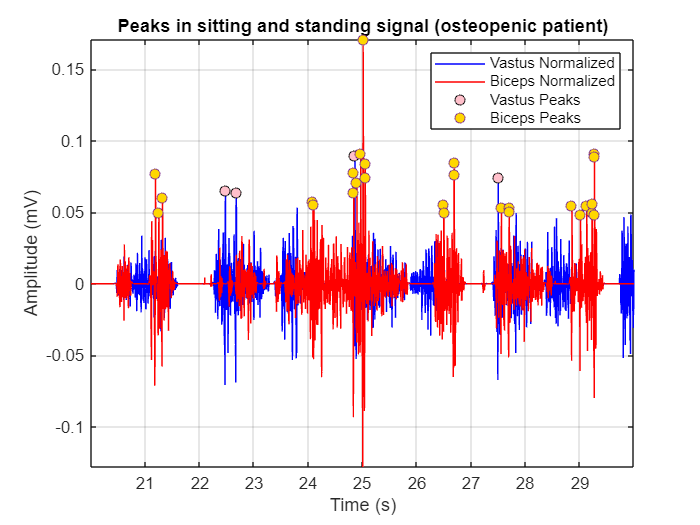

[pks, locs] = findpeaks(sit_stend_v, 'MinPeakHeight', 0.06); %SET THE CORRECT THRESHOLD
[pks1, locs1] = findpeaks(sit_stend_b, 'MinPeakHeight', 0.047); %SET THE CORRECT THRESHOLD

figure()
plot(t_sit_stend_v, sit_stend_v, 'b', t_sit_stend_v, sit_stend_b, 'r');
title('Peaks in sitting and standing signal (osteopenic patient)');
axis tight;
hold on;
plot(t_sit_stend_v(locs), pks, 'ko', 'MarkerFaceColor', '#FFC0CB');
plot(t_sit_stend_v(locs1), pks1, 'o', 'MarkerFaceColor', '#FFD700');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;
legend('Vastus Normalized', 'Biceps Normalized', 'Vastus Peaks', 'Biceps Peaks');
hold off;